# Analyzing ADCP Data with DOLfYN

The following example illustrates a straightforward workflow for analyzing Acoustic Doppler Current Profiler (ADCP) data utilizing MHKiT. MHKiT has integrated the Doppler Oceanographic Library for pYthoN (DOLfYN) codebase as a module to facilitate ADCP and Acoustic Doppler Velocimetry (ADV) data processing.

Here is a standard workflow for ADCP data analysis:

**1. Import Data**

**2. Review, QC, and Prepare the Raw Data:**

- Calculate or verify the correctness of depth bin locations

- Discard data recorded above the water surface or below the seafloor

- Assess the quality of velocity, beam amplitude, and/or beam correlation data

- Rotate Data Coordinate System

**3. Data Averaging:**

- If not already executed within the instrument, average the data into time bins of a predetermined duration, typically between 5 and 10 minutes

**4. Calculation of Speed and Direction**

**5. Visualizations**

**6. Saving and Loading DOLfYN datasets**

**7. Turbulence Statistics:** (Upcoming in MHKiT-MATLAB)

- Turbulence Intensity (TI)

- Power Spectral Densities

- Instrument Noise

- Turbulent Kinetic Energy (TKE) Dissipation Rate

- Noise-corrected TI

- TKE Components

- TKE Production

- TKE Balance

## 1. Importing Raw Instrument Data

One of DOLfYN's key features is its ability to directly import raw data from an Acoustic Doppler Current Profiler (ADCP) right after it has been transferred. In this instance, we are using a Nortek Signature1000 ADCP, with the data stored in files with an '.ad2cp' extension. This specific dataset represents several hours of velocity data, captured at 1 Hz by an ADCP mounted on a bottom lander within a tidal inlet. The list of instruments compatible with DOLfYN can be found in the [MHKiT DOLfYN documentation](https://mhkit-software.github.io/MHKiT/mhkit-python/api.dolfyn.html).

We'll start by importing the raw data file downloaded from the instrument. The `dolfyn_read` function processes the input raw file and converts the data into a MATLAB struct, typically called a Dataset, or `ds` for short. This Dataset includes several groups of variables:

- **Velocity**: Recorded in the coordinate system saved by the instrument (beam, XYZ, ENU)

- **Beam Data**: Includes amplitude and correlation data

- **Instrumental & Environmental Measurements**: Captures the instrument's bearing and environmental conditions

- **Orientation Matrices**: Used by DOLfYN for rotating through different coordinate frames.

Note: Before reading ADCP data with dolfyn_read, ensure your files are split into manageable chunks. DOLfYN performs best with files under 1GB. The file size depends primarily on your sampling frequency and deployment duration. Most ADCP manufacturers provide software tools or deployment settings to control output file size. Consult your instrument's documentation for specific guidance on file size configuration.

The `dolfyn_read` function parses the raw ADCP file into MATLAB.

ds = dolfyn_read('./examples/data/dolfyn/Sig1000_tidal.ad2cp');

Reading file ./examples/data/dolfyn/Sig1000_tidal.ad2cp


Display the contents and structure of the dataset by examining the `ds` variable below.

ds

ds = struct with fields:
                 coords: [1×1 struct]
                c_sound: [1×1 struct]
                   temp: [1×1 struct]
               pressure: [1×1 struct]
                heading: [1×1 struct]
                  pitch: [1×1 struct]
                   roll: [1×1 struct]
                    mag: [1×1 struct]
                  accel: [1×1 struct]
                   batt: [1×1 struct]
             temp_clock: [1×1 struct]
                  error: [1×1 struct]
                 status: [1×1 struct]
               ensemble: [1×1 struct]
                    vel: [1×1 struct]
                    amp: [1×1 struct]
                   corr: [1×1 struct]
              orientmat: [1×1 struct]
                  angrt: [1×1 struct]
            quaternions: [1×1 struct]
             temp_press: [1×1 struct]
            xmit_energy: [1×1 struct]
                 mag_b5: [1×1 struct]
               accel_b5: [1×1 struct]
               error_b5: [1×1 struct]
              status_b5: 

The function `dolfyn_plot` provides a simple api to visualize the data read by DOLFyN. Pass in the dataset, the dimension name and index. `dolfyn_plot` uses data found within the dataset attributes to determine the plot type and labels.

Before creating our visualizations, we'll define standard figure dimensions that will be used throughout this example. Setting consistent figure sizes ensures all plots are properly scaled and makes it easier to compare different aspects of the data. The viz_width and viz_height variables defined below will be passed to dolfyn_plot for each visualization.

viz_width = 1800;
viz_height = 300;

`dolfyn_plot` is a versatile visualization function for DOLfYN datasets. Here we use it to create histograms of velocity measurements across all depth bins. The function accepts the following key arguments:

- ds: our dataset structure

- 'vel': specifies the variable in `ds` that we want to plot

- 'dim', specifies the dimension we want to plot, 1:3: plots all three velocity components (typically east, north, up)

- 'width'/'height': control figure dimensions

- 'kind', 'hist': specifies we want histogram plots instead of the default time series

The resulting histograms help us identify potential outliers and assess the overall distribution of velocity measurements.

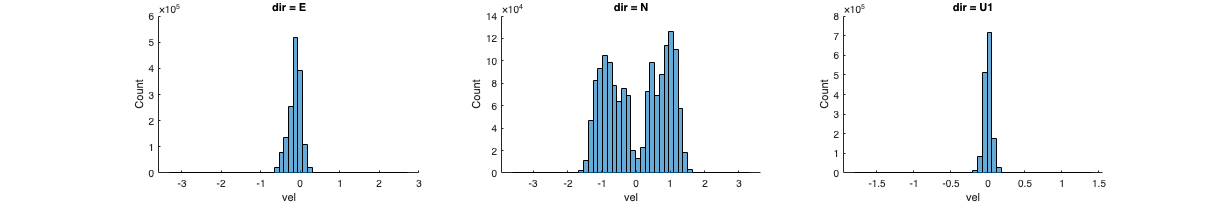

dolfyn_plot(ds, 'vel', 'dim', 1:3, 'width', viz_width, 'height', viz_height, 'kind', 'hist');

Now we will plot the data with a logarithmic y scale, We are looking for outliers, particularly in the extremes of the dataset.

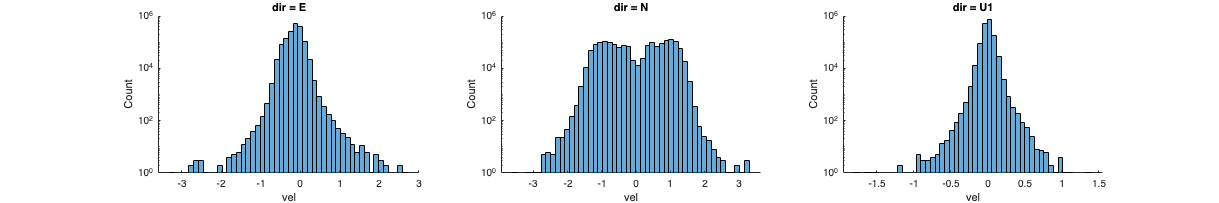

dolfyn_plot(ds, 'vel', 'dim', 1:3, 'width', viz_width, 'height', viz_height, 'kind', 'hist', 'scale', 'logy');

For this dataset `./examples/data/dolfyn/Signature1000_tidal.ad2cp` the histogram plots show that our velocity measurements are symmetrically distributed and centered around 0 m/s, with no significant spikes or discontinuities at the extremes. This indicates the data quality is reasonable and we can proceed with our analysis without removing outliers. If we had seen unusual peaks at extreme values or a highly asymmetric distribution, we would need to investigate those measurements more carefully.

Note: While this visual inspection is a good first step, a comprehensive quality control process would typically include additional statistical tests and instrument-specific checks. For this example, we'll proceed with our initial assessment.

We are also going to calculate and define the colorbar to keep comparisons velocity plots consistent The velocity colorbar limits are determined using percentile-based thresholds to reduce the impact of outliers while maintaining symmetry around zero. First, the 1st and 99th percentiles of the velocity data are calculated, capturing the central 98% of the data distribution. Then, the larger absolute value between these percentiles is used to set symmetric positive and negative limits. The final values are rounded to whole numbers for a cleaner colorbar scale. This approach ensures the colorbar:

- Excludes extreme outliers that might compress the color scale

- Maintains symmetry around zero for proper visualization of bidirectional flow

- Preserves the true scale of the dominant velocity magnitudes

- Uses whole numbers for easier readability

floor_percentile = 1;
ceiling_percentile = 99;

% Calculate 1st and 99th percentiles of the flattened velocity array
pct_min = prctile(ds.vel.data(:), floor_percentile);
pct_max = prctile(ds.vel.data(:), ceiling_percentile);

% Determine the larger magnitude between percentile bounds
max_abs = max(abs([pct_min, pct_max]));

% Set symmetric colorbar limits using the larger magnitude, rounded to whole numbers
vel_cbar_min = -ceil(max_abs);
vel_cbar_max = ceil(max_abs);

Now we'll create our first comprehensive visualization of the ADCP velocity data. dolfyn_plot will generate three panels showing:

- East velocity component (dim=1): positive values indicate eastward flow

- North velocity component (dim=2): positive values indicate northward flow

- Up velocity component (dim=3): positive values indicate upward flow

Each panel shows:

- X-axis: Time

- Y-axis: Distance from ADCP (range)

- Colors: Velocity magnitude (in m/s)

- Blues/Negatives: flow in negative direction

- Reds/Positives: flow in positive direction

We use our previously calculated `vel_cbar_min` and `vel_cbar_max` to ensure the color scales are consistent and centered around zero across all plots. This makes it easier to compare velocity magnitude across directions.

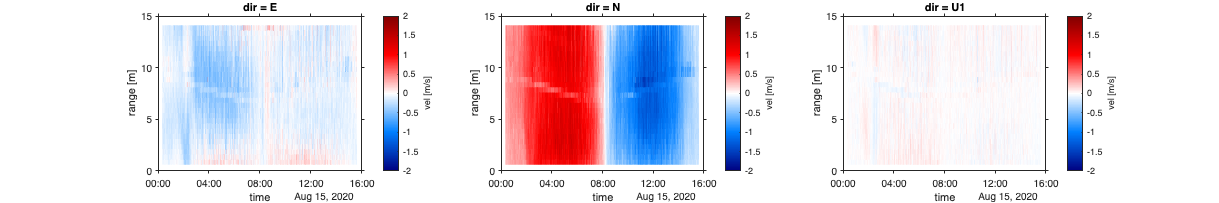

dolfyn_plot(ds, 'vel', 'dim', 1:3, ...
    'width', viz_width, 'height', viz_height, ...
    'cbar_min', vel_cbar_min, 'cbar_max', vel_cbar_max);

Velocity dimensions are located in `ds.vel.dims`

ds.vel.dims

ans = 1×3 cell array
    {'time'}    {'range'}    {'dir'}


The specifications for each coordinate are located in `ds.coords.(dim)`

ds.coords.dir

ans = 1×4 cell array
    {'E'}    {'N'}    {'U1'}    {'U2'}


## 2. Initial Steps for Data Quality Control (QC)

**2.1: Set the Deployment Height**

When using Nortek instruments, the deployment software does not factor in the deployment height. The deployment height represents the position of the Acoustic Doppler Current Profiler (ADCP) within the water column.

In this context, the center of the first depth bin is situated at a distance that is the sum of three elements:

- Deployment height (the ADCP's position in the water column)

- Blanking distance (the minimum distance from the ADCP to the first measurement point)

- Cell size (the vertical distance of each measurement bin in the water column)

To ensure accurate readings, it is critical to calibrate the 'range' coordinate to make '0' correspond to the seafloor. This calibration can be achieved using the `set_range_offset` function. This function is also useful when working with a down-facing instrument as it helps account for the depth below the water surface.

For those using a Teledyne RDI ADCP, the TRDI deployment software will prompt the user to specify the deployment height/depth during setup. If there's a need for calibration post-deployment, the `set_range_offset` function can be utilized in the same way as described above.

The ADCP transducers were measured to be 0.6 meters from the feet of the lander

ds = set_range_offset(ds, 0.6);

Range values can be checked by calculating min, max, and spacing values.

% Create a table summarizing the range characteristics
range_stats = table({"Maximum"; "Minimum"; "Mean Spacing"; "Max Spacing"; "Min Spacing"}, ...
    round([max(ds.coords.range); ...
          min(ds.coords.range); ...
          mean(diff(ds.coords.range)); ...
          max(diff(ds.coords.range)); ...
          min(diff(ds.coords.range))] * 100) / 100, ...
    'VariableNames', {'Range Metric', 'Value'});

format short;
range_stats

range_stats = 5×2 table
       Range Metric       Value
    __________________    _____

    {["Maximum"     ]}    14.7 
    {["Minimum"     ]}     1.2 
    {["Mean Spacing"]}     0.5 
    {["Max Spacing" ]}     0.5 
    {["Min Spacing" ]}     0.5 


**2.2. Discard Data Above Surface Level**

To reduce computational load, we can exclude all data at or above the water surface level. Since the instrument was oriented upwards, we can utilize the pressure sensor data along with the function `water_depth_from_pressure`. However, this approach necessitates that the pressure sensor was calibrated or 'zeroed' prior to deployment. If the instrument is facing downwards or doesn't include pressure data, the function `water_depth_from_pressure` can be used to detect the seabed or water surface.

It's important to note that Acoustic Doppler Current Profilers (ADCPs) do not measure water salinity, so the user will need to supply this information to the function. The dataset returned by this function includes an additional variable, "depth". If `water_depth_from_pressure` is invoked after `set_range_offset`, "depth" represents the distance from the water surface to the seafloor. Otherwise, it indicates the distance to the ADCP pressure sensor. The `water_depth_from_pressure` function allows the user to specified salinity value in Practical Salinity Units (PSU).

water_salinity_psu = 31;
ds = water_depth_from_pressure(ds, 'salinity', water_salinity_psu);

Visualizing Depth

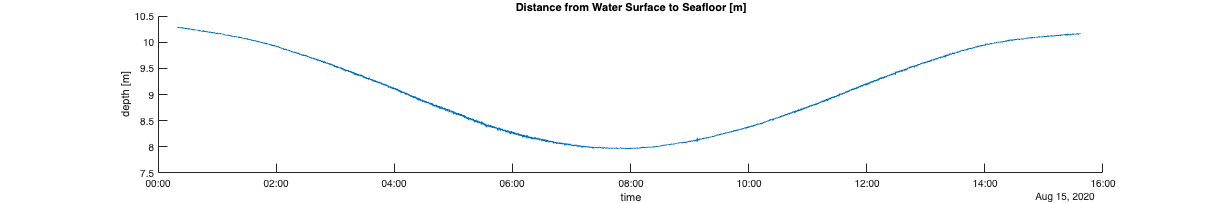

dolfyn_plot(ds, 'depth', 'width', 800, 'height', 400);
title('Distance from Water Surface to Seafloor [m]');

After determining the "depth", the `remove_surface_interference` function can be used to discard data in depth bins near or above the actual water surface. This function calculates a range limit based on the beam angle and cell size, where surface interference is expected to occur at distances greater than `range * cos(beam angle) - cell size`. The beam angle accounts for the acoustic spread of the ADCP signal (typically 20-25 degrees). To exclude the found surface interference data DOLfYN sets data above this threshold to NaN.

ds = remove_surface_interference(ds);

Visualizing removal of surface interference

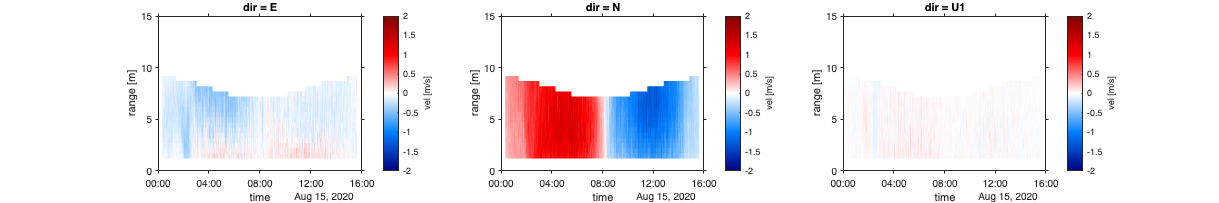

dolfyn_plot(ds, 'vel', 'dim', 1:3, ...
    'width', viz_width, 'height', viz_height, ...
    'cbar_min', vel_cbar_min, 'cbar_max', vel_cbar_max);

**Correlation**

It's beneficial to also review data from the other beams. A significant portion of this data is of high quality. To avoid discarding valuable data with lower correlations, which could be due to natural variations, we can use the `correlation_filter`. This function assigns a value of NaN (not a number) to velocity values corresponding to correlations below 50%.

However, it's important to note that the correlation threshold is dependent on the specifics of the deployment environment and the instrument used. It's not unusual to set a threshold as low as 30%, or even to forgo the use of this function entirely.

ds = correlation_filter(ds, 'thresh', 50);

Visualizing Correlation Data

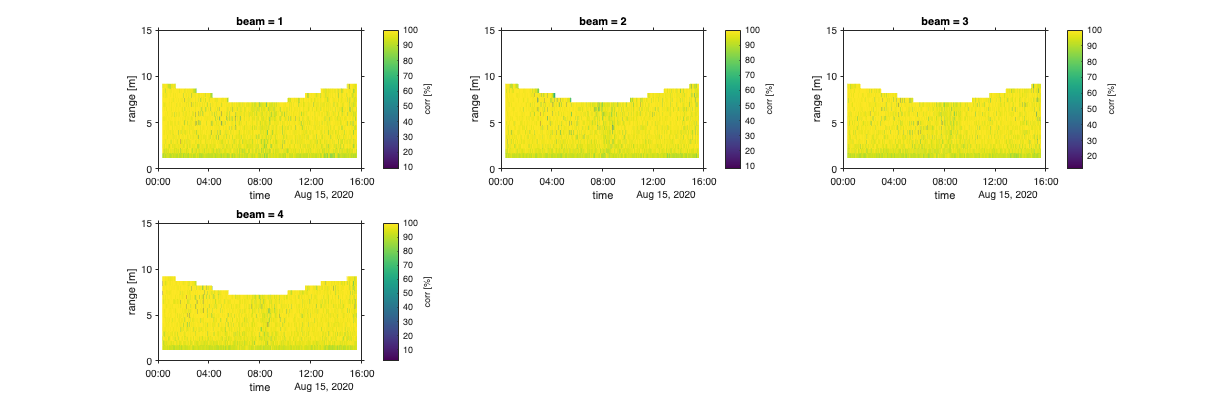

dolfyn_plot(ds, 'corr', 'dim', 1:4, 'width', viz_width, 'height', viz_height * 2);

**2.4 Rotate Data Coordinate System**

After cleaning the data, the next step is to rotate the velocity data into accurate East, North, Up (ENU) coordinates.

ADCPs utilize an internal compass or magnetometer to determine magnetic ENU directions. You can use the set_declination function to adjust the velocity data according to the magnetic declination specific to your geographical coordinates. This declination can be looked up online for specific coordinates.

Instruments save vector data in the coordinate system defined in the deployment configuration file. To make this data meaningful, it must be transformed through various coordinate systems ("beam"<->"inst"<->"earth"<->"principal"). This transformation is accomplished using the `rotate2` function. If the "earth" (ENU) coordinate system is specified, DOLfYN will automatically rotate the dataset through the required coordinate systems to reach the "earth" coordinates.

In this case, since the ADCP data is already in the "earth" coordinate system, the `rotate2` function will return the input dataset without modifications. The `set_declination` function will work no matter the coordinate system.

ds = set_declination(ds, 15.8);
ds = rotate2(ds, 'earth');

Data is already in the earth coordinate system

To rotate into the principal frame of reference (streamwise, cross-stream, vertical), if desired, we must first calculate the depth-averaged principal flow heading and add it to the dataset attributes. Then the dataset can be rotated using the same `rotate2` function.

ds.attrs.principal_heading = calc_principal_heading(squeeze(ds.vel.data), true);
disp(ds.attrs.principal_heading);

   11.2768



ds_streamwise = rotate2(ds, 'principal');

Visualize Streamwise Velocity

First we will verify the transformation by visually inspecting the histogram and checking for outliers

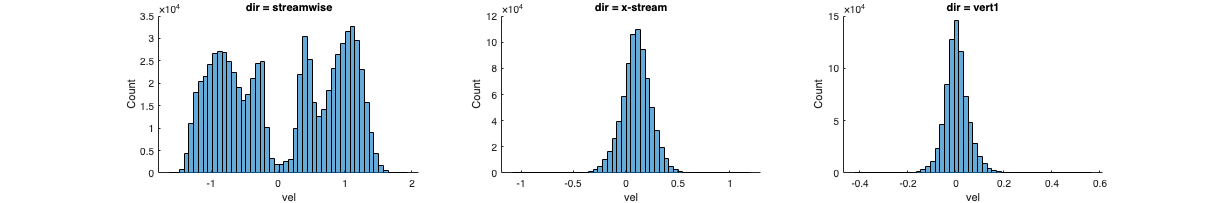

dolfyn_plot(ds_streamwise, 'vel', 'dim', 1:3, 'width', viz_width, 'height', viz_height, 'kind', 'hist');

Next we will plot streamwise and cross-stream velocity

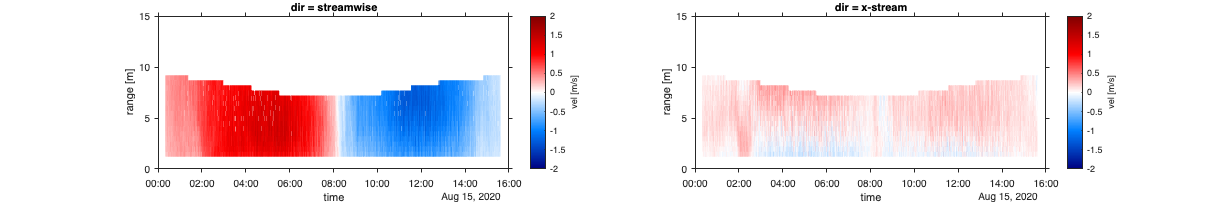

dolfyn_plot(ds_streamwise, 'vel', 'dim', 1:2, ...
    'width', viz_width, 'height', viz_height, ...
    'cbar_min', vel_cbar_min, 'cbar_max', vel_cbar_max);

## 3. Average the Data

As this deployment was configured in "burst mode", a standard step in the analysis process is to average the velocity data into time bins.

However, if the instrument was set up in an "averaging mode" (where a specific profile and/or average interval was set, for instance, averaging 5 minutes of data every 30 minutes), this step would have been performed within the ADCP during deployment and can thus be skipped.

The function `average_by_dimension` is used to average the data by dimension. To average the data into time bins (also known as ensembles), the sampling rate and averaging period must be defined. DOLfYN stores the sampling frequency [Hz] in `.attrs.fs`. The averaging period should be specified in seconds. We can then use these values to calculate the number of samples to average.

sampling_frequency_hz = ds.attrs.fs;
averaging_period_seconds = 300; % 5 minutes

averaging_samples = int32(round(averaging_period_seconds * sampling_frequency_hz));

Once the averaging samples count has been calculated we can average the dataset by time by passing the original dataset, the number of samples to average, and the dimension ('time').

Important note about sample size: When the total number of samples is not evenly divisible by your averaging period, DOLfYN will discard the remaining samples at the end of the dataset. For example, with:

- Total samples: 55000

- Averaging period: 300 samples

- 55000 ÷ 300 = 183.33 (not a whole number)

- Last 100 samples will be discarded

To avoid losing data, you can:

- Combine multiple datasets together

- Adjust your averaging period to evenly divide into your total samples

- Trim your dataset to a length that's divisible by your averaging period

- Accept the loss of the partial bin at the end if it's not critical

In this example, losing 100 samples (100/55000 = 0.18% of data) is acceptable for our analysis.

ds_avg = average_by_dimension(ds, averaging_samples, 'time');

Plotting the Summary Data

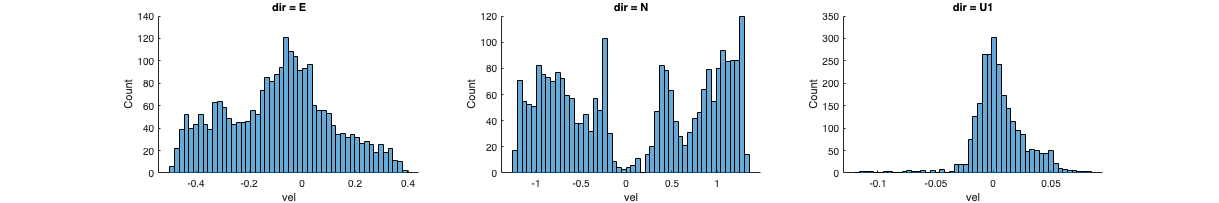

dolfyn_plot(ds_avg, 'vel', 'dim', 1:3, 'width', viz_width, 'height', viz_height, 'kind', 'hist');

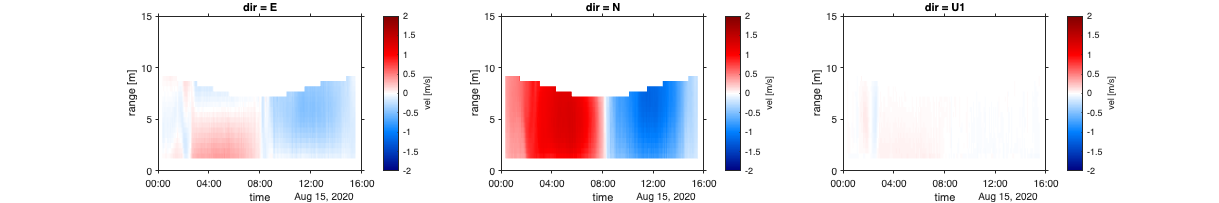


dolfyn_plot(ds_avg, 'vel', 'dim', 1:3, ...
    'width', viz_width, 'height', viz_height, ...
    'cbar_min', vel_cbar_min, 'cbar_max', vel_cbar_max);

## 4. Calculate Current Speed and Direction

The `calculate_horizontal_speed_and_direction` function processes our east and north velocity components to compute two key measurements: current speed (U_mag) and direction (U_dir). The speed is calculated as the magnitude of the horizontal velocity components and stored in ds_avg.U_mag, using the same units as the input velocities (typically m/s).

Direction (U_dir) handling depends on the coordinate system (ds.coord_sys):

- For "earth" coordinates: Direction is measured in degrees clockwise from true North [0-360°]

- For other coordinates (e.g., "principal", "inst", "beam"): Direction is measured in degrees clockwise from East/streamwise component [0-360°]

For example in "earth" coordinates:

- U_dir = 90° means the current is flowing towards the east

- U_dir = 180° means the current is flowing towards the south

- U_dir = 270° means the current is flowing towards the west

See 'help calculate_horizontal_speed_and_direction' for complete details on coordinate systems and direction calculations.

ds_avg = calculate_horizontal_speed_and_direction(ds_avg);

ds_avg.U_mag

ans = struct with fields:
             data: [183×28 double]
             dims: {'time'  'range'}
           coords: [1×1 struct]
            units: "m s-1"
    standard_name: "sea_water_speed"
        long_name: "Water Speed"


ds_avg.U_dir

ans = struct with fields:
             data: [183×28 double]
             dims: {'time'  'range'}
           coords: [1×1 struct]
            units: "degrees clockwise from N"
    standard_name: "sea_water_to_direction"
        long_name: "Water To Direction"


## 5. Visualize Current Speed and Direction

Now we'll create two key visualizations to help understand the flow patterns:

**1. Current Speed Plot:**

- Shows the magnitude of water movement at each depth and time

- Uses a blue colormap where darker colors indicate faster flow

- Includes a blue line showing the water surface elevation

- X-axis: Time of day

- Y-axis: Distance from seafloor (altitude)

**2. Current Direction Plot:**

- Shows where the water is flowing TO at each depth and time

- Uses a circular colormap to represent the full 360° of possible directions

- Includes the same water surface elevation line

- Same axes as the speed plot for easy comparison

Both plots use the time-averaged data (ds_avg) we created earlier, with each point representing a 5-minute average.

% Create color map for both visualizations
blues = blues_colormap(256);
darkest_blue = blues(end,:);

Current Speed Visualization

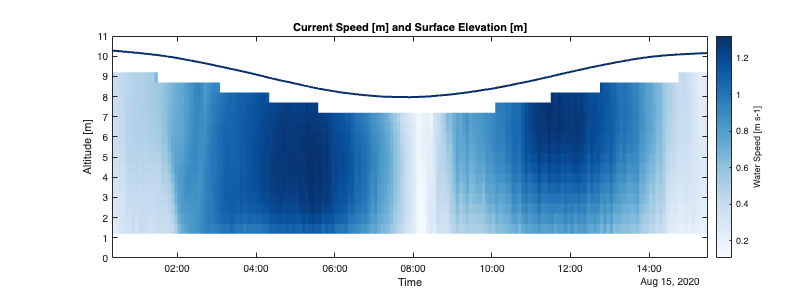

% Create color map for both visualizations
blues = blues_colormap(256);
darkest_blue = blues(end,:);

fig = figure;
viz_width = 800;
fig.Position = [100 100 viz_width viz_height];

ax = axes('Position', [0.14 0.14 0.8 0.74]);

time = datetime(ds_avg.coords.time, 'ConvertFrom', 'posixtime');
range = ds_avg.coords.range;
speed = squeeze(ds_avg.U_mag.data);
speed = speed';
depth = ds_avg.depth.data;
y_min = 0;
y_max = int32(max(ds.depth.data) + 1);

[T, R] = meshgrid(time, range);
pcolor(T, R, speed);
shading flat;

colormap(blues);

% Ensure that the box and ticks are on top of the visualization
set(gca, 'Layer', 'top', 'Box', 'on')
set(gca, 'XGrid', 'off', 'YGrid', 'off')
set(gca, 'TickDir', 'in')
set(gca, 'LineWidth', 1)

hold on;

% Add a line denoting water surface depth using the darkest blue from the colormap
plot(time, depth, 'Color', darkest_blue, 'LineWidth', 2);

xlabel('Time');
ylabel('Altitude [m]');
ylim([y_min y_max]);

ax.XAxis.TickLabelFormat = 'HH:mm';

c = colorbar;
c.Label.String = sprintf('%s [%s]', ds_avg.U_mag.long_name, ds_avg.U_mag.units);
title('Current Speed [m] and Surface Elevation [m]');

hold off;

Current "To" Direction (Degrees CW from True North) Visualization

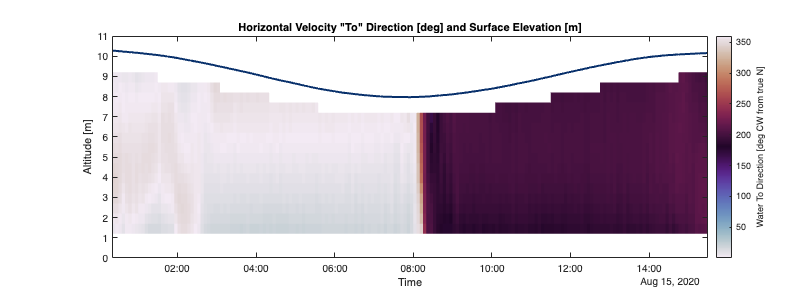

fig = figure;
fig.Position = [100 100 viz_width viz_height];

ax = axes('Position', [0.14 0.14 0.8 0.74]);

direction = squeeze(ds_avg.U_dir.data);
direction = direction';

pcolor(T, R, direction);
shading flat;
colormap(twilight);

set(gca, 'Layer', 'top', 'Box', 'on')
set(gca, 'XGrid', 'off', 'YGrid', 'off')
set(gca, 'TickDir', 'in')
set(gca, 'LineWidth', 1)

hold on;

% Plot water surface depth
plot(time, depth, 'Color', darkest_blue, 'LineWidth', 2);

xlabel('Time');
ylabel('Altitude [m]');
ylim([y_min y_max]);

ax.XAxis.TickLabelFormat = 'HH:mm';

c = colorbar;
c.Label.String = sprintf('%s [deg CW from true N]', ds_avg.U_dir.long_name);

title('Horizontal Velocity "To" Direction [deg] and Surface Elevation [m]');

hold off;

## 6. Save Data

Datasets can be saved and loaded using the write_netcdf and read_netcdf functions, respectively.

% Uncomment these lines to save and load to your current working directory
% write_netcdf(ds, 'your_data.nc');
% ds_saved = read_netcdf('your_data.nc');

## 7. Turbulence Statistics

In the next release of MHKiT-MATLAB turbulence statistics calculations and visualizations will be added.